clear 
clc
fs = 44.1e3;
sweepDur = 5;
silenceDur = 1;
tone = sweeptone(sweepDur,silenceDur,fs);
toneNoSilence = tone(1:end-round(silenceDur*fs)-1)

toneNoSilence =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


t = 0:1/fs:sweepDur+silenceDur-1/fs

t =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


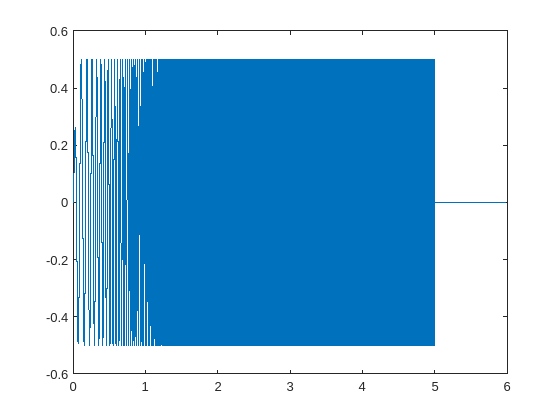

%t = linspace(0,length(tone)/fs,length(tone))
plot(t,tone)

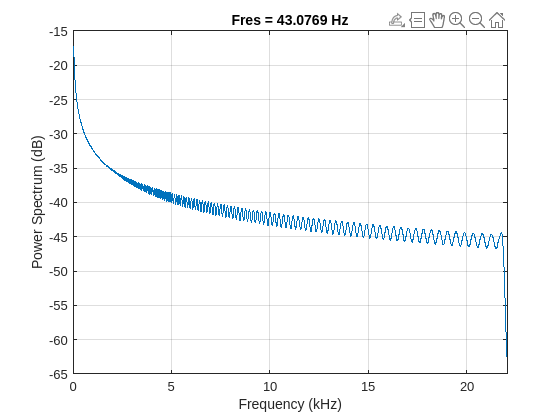

pspectrum(tone,fs)


cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);
FIRULA1 = fir1(60, 2*cfULA1/fs, 'low');
FIRULA2 = fir1(60, 2*cfULA2/fs, 'bandpass');
FIRULA3 = fir1(60, 2*cfULA3/fs, 'high');

toneFiltered = filter(FIRULA1,1,tone) + filter(FIRULA2,1,tone) %+ filter(FIRULA3,1,tone);

toneFiltered =          0
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


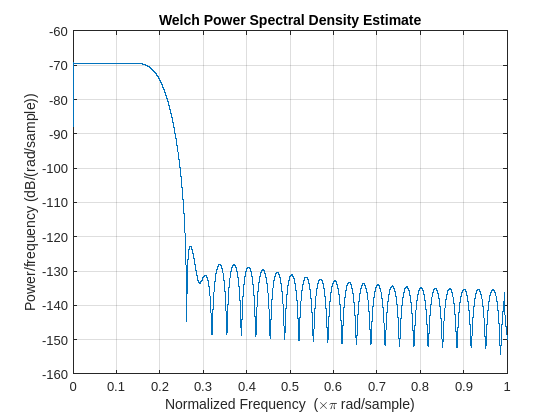

impulse = impzest(tone, toneFiltered);
%impulse = impulse(1:101);

%impulse = impzest(tone,tone)
pwelch(impulse,fs)

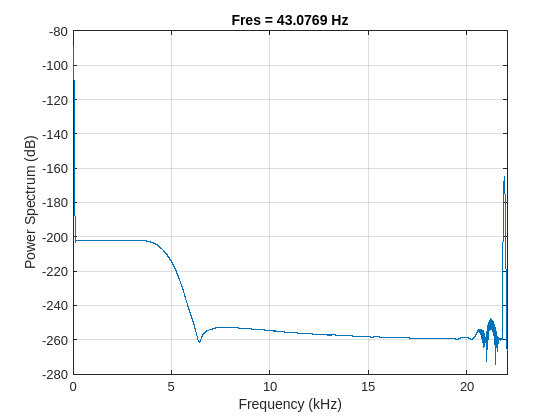

pspectrum(impulse,fs) %psectrum STINKER